% 1 uzduotis

S.pavardes = {'Jonaitis','Petraitis','Kazlauskas'};
S.amzius = [20 21 22];

disp('Pradine struktura:')

Pradine struktura:


disp(S)

    pavardes: {'Jonaitis'  'Petraitis'  'Kazlauskas'}
      amzius: [20 21 22]




% Lauku tvarkos pakeitimas

S2 = orderfields(S,{'amzius','pavardes'});

disp('Pakeista struktura:')

Pakeista struktura:


disp(S2)

      amzius: [20 21 22]
    pavardes: {'Jonaitis'  'Petraitis'  'Kazlauskas'}



% 2 uzduotis

format compact

while true

    x = input('Iveskite x: ');
    y = input('Iveskite y: ');

    if x ~= y && x ~= 0 && y ~= 0
        break
    end

    disp('x ir y turi buti skirtingi ir nelygus nuliui')
end

b = atan(y/x);

disp(' n       Kaire_puse                Desine_puse              Skirtumas')

 n       Kaire_puse                Desine_puse              Skirtumas



for n = 1:10

    kaire = (cos(b)+1i*sin(b))^n;

    desine = cos(n*b)+1i*sin(n*b);

    skirtumas = abs(kaire-desine);

    fprintf('%2d   %12.6f+%12.6fi   %12.6f+%12.6fi   %e\n',...
        n,...
        real(kaire),imag(kaire),...
        real(desine),imag(desine),...
        skirtumas);

end

 1       0.980581+    0.196116i       0.980581+    0.196116i   0.000000e+00
 2       0.923077+    0.384615i       0.923077+    0.384615i   0.000000e+00
 3       0.829722+    0.558177i       0.829722+    0.558177i   1.570092e-16
 4       0.704142+    0.710059i       0.704142+    0.710059i   1.110223e-16
 5       0.551214+    0.834364i       0.551214+    0.834364i   1.110223e-16
 6       0.376878+    0.926263i       0.376878+    0.926263i   1.110223e-16
 7       0.187904+    0.982187i       0.187904+    0.982187i   3.510833e-16
 8      -0.008368+    0.999965i      -0.008368+    0.999965i   2.474825e-16
 9      -0.204315+    0.978905i      -0.204315+    0.978905i   3.342214e-16
10      -0.392326+    0.919826i      -0.392326+    0.919826i   3.140185e-16


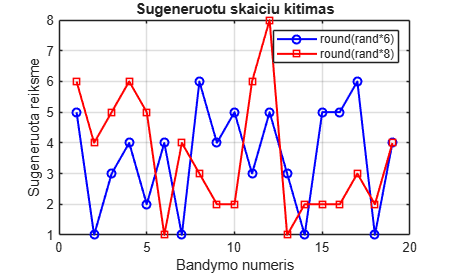

% Papildoma uzduotis

A = [];
B = [];

while true

    a = round(rand*6);
    b = round(rand*8);

    A = [A a];
    B = [B b];

    if a == b
        break
    end

end

figure

plot(A,'b-o','LineWidth',1.5)
hold on

plot(B,'r-s','LineWidth',1.5)

title('Sugeneruotu skaiciu kitimas')
xlabel('Bandymo numeris')
ylabel('Sugeneruota reiksme')

legend('round(rand*6)','round(rand*8)')
grid on